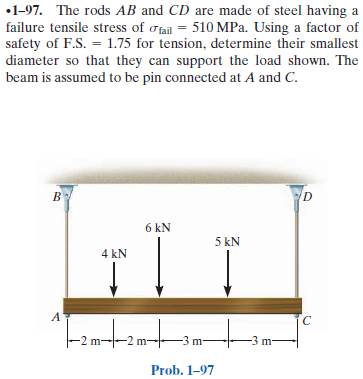

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-97P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-97P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rc', 10*u.m);
b = b.add('concentrated', 'force', -4*u.kN, 2*u.m);
b = b.add('concentrated', 'force', -6*u.kN, 4*u.m);
b = b.add('concentrated', 'force', -5*u.kN, 7*u.m);
b.L = 10*u.m; 

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(4821\,m^{2}-83\,x^{2}\right)}{60\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ \frac{43\,x^{3}+240\,x^{2}\,m-5301\,x\,m^{2}+320\,m^{3}}{60\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,4\,m\right]\\ -\frac{17\,x^{3}-960\,x^{2}\,m+8181\,x\,m^{2}-4160\,m^{3}}{60\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(4\,m,7\,m\right]\\ -\frac{\left(x-10\,m\right)\,\left(67\,x^{2}-1340\,x\,m+2131\,m^{2}\right)}{60\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }7\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{1607\,m^{2}-83\,x^{2}}{20\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ \frac{43\,x^{2}+160\,x\,m-1767\,m^{2}}{20\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,4\,m\right]\\ -\frac{17\,x^{2}-640\,x\,m+2727\,m^{2}}{20\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(4\,m,7\,m\right]\\ -\frac{67\,x^{2}-1340\,x\,m+5177\,m^{2}}{20\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }7\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{83\,x}{10}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ \frac{43\,x+80\,m}{10}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,4\,m\right]\\ -\frac{17\,x-320\,m}{10}\,\mathrm{kN} & \text{ if }x\in \left(4\,m,7\,m\right]\\ -\frac{67\,\left(x-10\,m\right)}{10}\,\mathrm{kN} & \text{ if }7\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{83}{10}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ \frac{43}{10}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,4\,m\right]\\ -\frac{17}{10}\,\mathrm{kN} & \text{ if }x\in \left(4\,m,7\,m\right]\\ -\frac{67}{10}\,\mathrm{kN} & \text{ if }7\,m<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 8.3\,\mathrm{kN}\\ \mathrm{Rc} & 6.7\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

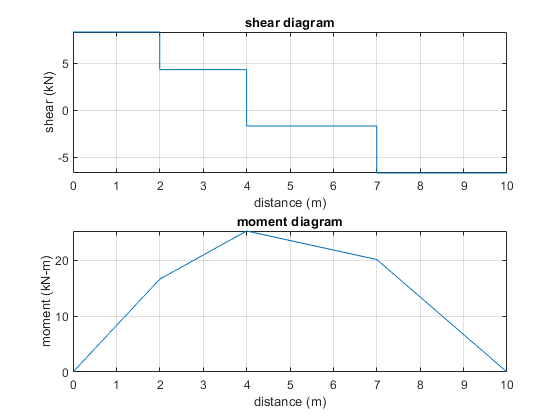

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# allowable tensile stress

sigma_fail = 510*u.MPa;
FS = 1.75;
sigma_allow = sigma_fail/FS;
sigma_allow_vpa = vpa(sigma_allow, 5) %#ok<NASGU> 

$$sigma\_allow\_vpa = 291.43\,\mathrm{MPa}$$

# minimum diameter design for rod AB

d_AB = sym('d_AB', 'positive');
R_AB = rs.Ra;
A_AB(d_AB) = sympi*d_AB^2/4;
d_AB = solve(sigma_allow == R_AB/A_AB);
d_AB = combine(simplify(rewrite(combine(d_AB), u.mm)));
d_AB_vpa = vpa(d_AB, 3) %#ok<NASGU> 

$$d\_AB\_vpa = 6.02\,\mathrm{mm}$$

# minimum diameter design for rod CD

d_CD = sym('d_CD', 'positive');
R_CD = rs.Rc;
A_CD(d_CD) = sympi*d_CD^2/4;
d_CD = solve(sigma_allow == R_CD/A_CD);
d_CD = combine(simplify(rewrite(combine(d_CD), u.mm)));
d_CD_vpa = vpa(d_CD, 3) %#ok<NASGU> 

$$d\_CD\_vpa = 5.41\,\mathrm{mm}$$

# clean up

addvar(y);
setassum(old_assum, 'Mode', 'clear');
clear old_assum;
clear ra_vpa;
clear sigma_allow_vpa;
clear d_AB_vpa;
clear d_CD_vpa;